# **This MATLAB Live Script compares analytic and numerical**

# **solutions of CRPS of **$P=P_{\mathrm{III}} \left(\mu ,\sigma \mathrm{²},\rho \right)$** of Vrugt, WRR (2024)**

**Quantile form of the CRPS [in negative orientation!]**


$$\mathrm{CRPS}\left(P,\omega \right)=\omega \left(2F\left(\omega \right)-1\right)-2\int_0^1 \tau F^{-1} \left(\tau \right)\mathrm{d}\tau +2\int_{F\left(\omega \right)}^1 F^{-1} \left(\tau \right)\mathrm{d}\tau$$


**Quantile function **$F^{-1} \left(\tau \right)$ **(= inverse CDF)** **of univariate Pearson type III distribution  **$P=P_{\mathrm{III}} \left(\mu ,\sigma \mathrm{²},\rho \right)$** with mean **$\mu$, **variance**  $\sigma \mathrm{²}$ **and skewnesss** $\rho$. **We can reparameterize the PIII-distribution and define** $\xi =\mu -2\frac{\sigma }{\rho }$, $a=\frac{4}{\rho^2 }$ and $b=\frac{1}{2}\sigma \left|\rho \right|$ **as its location, shape and scale parameters, respectively, to yield**, $P=P_{\mathrm{III}} \left(\xi ,a,b\right)$. **Then, the CDF becomes**


$$F_P \left(x,\xi ,a,b\right)=\left\lbrace \begin{array}{ll}
\frac{1}{\Gamma \left(a\right)}\gamma \left(a,b^{-1} \left(x-\xi \right)\right) & \mathrm{if}\;\rho >0\\
\frac{1}{\Gamma \left(a\right)}\Gamma \left(a,b^{-1} \left(\xi -x\right)\right) & \mathrm{if}\;\rho <0
\end{array}\right.$$


**where** $x,\xi ,a,b\in \mathrm{R},a>0,b>0$ **and**


$$\Gamma \left(a,q\right)=\int_q^{\infty } t^{a-1} \exp \left(-t\right)\;\mathrm{d}\;t$$


**and**


$$\gamma \left(a,q\right)=\int_0^q t^{a-1} \exp \left(-t\right)\;\mathrm{d}\;t$$


**denote the upper and lower incomplete gamma functions, respectively.**

**Background on PIII distribution: https://arxiv.org/pdf/2011.01332.pdf**

**PDF: Page 18 of** [https://library.wmo.int/doc_num.php?explnum_id=1695](https://library.wmo.int/doc_num.php?explnum_id=1695)

**f = @(x,a,b,xi) (abs(x-xi)/b).^(a-1) ./ (abs(b)*gamma(a)) .* exp( - abs(x-xi)/b); **

**abs(x-xi) as "b" is always positive in our implementation --> is easier to derive analytic solution for both cases (rho<0, and rho>0)**

**Reference**:

Vrugt, J. A. (2024). **Distribution-based model evaluation and diagnostics: Elicitability, propriety, and scoring rules for hydrograph functionals**. *Water Resources Research*, 60,e2023WR036710, [https://doi.org/10.1029/2023WR036710](https://doi.org/10.1029/2023WR036710)

Written by **Jasper A. Vrugt**

close all hidden; clear variables; clc

`Define parameter values of the GEV distribution forecast `$P=P_{\mathrm{III}} \left(\mu ,\sigma \mathrm{²},\rho \right)$

mu = 5;                         % mean of LPIII distribution
s2 = pi;                        % variance of LPIII distribution
rho = 2.0;                      % skewness of LPIII distribution
n = 1000;                       % number of measurements (w = omega)

`No need to change from here`

if rho == 0
    fprintf('PIII(mu,s2,0) --> N(mu,s2), thus use CRPS_normal.mlx instead\n');
    return
end
s = sqrt(s2);                   % Standard deviation
%mu = 2*sigma/rho;              % So that xi = 0
xi = mu - 2*s/rho;              % Location parameter    
a = 4/s2;                       % Scale parameter: Hosking and Wallis formulation 
b = 1/2*s*abs(rho);             % abs(rho) --> b > 0; works with xi = 0
%binv = 1/b;                     % inverse scale parameter
F_G = @(w,a,b) gamcdf(w,a,b);   % CDF of gamma distribution

`Sample ensemble from `$P=P_{\mathrm{III}} \left(\xi ,a,b\right)$` --> for numerical estimate of CRPS`

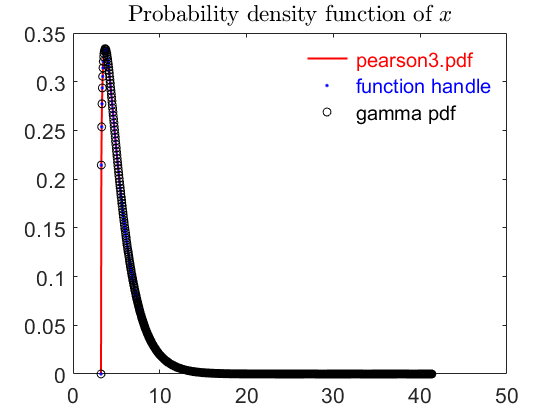

fcst_PIII = pearson3_rnd(a,b,xi,rho,1000,2000);
% Now use samples to determine min/max for drawing verifying observations
r = range(fcst_PIII(:));
switch sign(rho)
    case -1 % x \in (-inf,xi]
        w_min = min(fcst_PIII(:)) - r/10; w_max = xi - eps;
    case 1 % x \in [xi,inf)
        w_min = xi + eps; w_max = max(fcst_PIII(:)) + r/10;
end
% Draw materializing observations
W = unifrnd(w_min,w_max,n,1); 
% Generate equally-spaced x-values
x = linspace(w_min,w_max,1001); 
% Now PIII-toolbox downloaded from Mathworks
plot(x,pearson3_pdf(x,a,b,xi,rho),'r','markerfacecolor','w', ...
    'linewidth',1.5); hold on;
% Define PDF using anonymous function handle
f_piii = @(x) (abs(x-xi)/b).^(a-1) ./ (abs(b)*gamma(a)) .* ...
    exp( - abs(x-xi)/b); 
plot(x,f_piii(x),'b.');
% --> IDENTICAL

% With xi = 0; the PIII is equal to gamma(a,b)
% But lets try with gamma distribution when xi \neq 0
if rho < 0, x_star = xi - x; else, x_star = x - xi; end
plot(x,gampdf(x_star,a,b),'ko');
set(gca,'fontsize',16);
legend('\color{red} pearson3.pdf','\color{blue} function handle','\color{black} gamma pdf',...
    'box','off','fontsize',15);
title('Probability density function of $x$','interpreter','latex','fontsize',17);

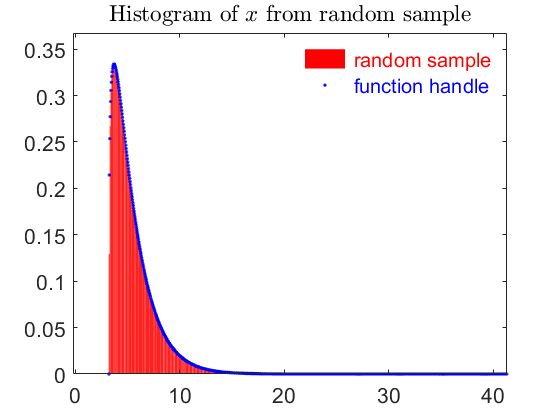


% Make a histogram and check whether ensemble satisfies known PDF
nbins = 400;
[pdf_hat,B] = histcounts(fcst_PIII(:),nbins,'normalization','pdf');
xb = 1/2*(B(1:nbins) + B(2:nbins+1)); r = range(xb);
figure(2),bar(xb,pdf_hat,'r'); axis([xb(1) - r/10 ...
    xb(nbins) + r/10 0 1.1*max(pdf_hat)]); hold on;
% plot Correct PDF on top
plot(x,f_piii(x),'b.','linewidth',2);
set(gca,'fontsize',16);
legend('\color{red} random sample','\color{blue} function handle','box','off','fontsize',15);
title('Histogram of $x$ from random sample','interpreter','latex','fontsize',17);

% --> PDF OF ENSEMBLE SHOULD MATCH PDF OF PIII(mu,s2,rho): Indeed, identical

% Compute CRPS of PIII(mu,s2,rho) for all n verifying observations =
% Equation I36 of Appendix I of paper
z_W = abs(W - xi); 
crps_an = 2 * 4^(-a)*abs(b)/beta(a,a) + a*b*(2*F_G(z_W,a+1,b) - 1) ...
    + z_W .* ( 1 - 2*F_G(z_W,a,b) );
% Compute the CRPS numerically using forecast ensemble and Weibull plotting position
[meanCRPS,crps_num,num_nan] = crp_score(fcst_PIII,W,'weib',4);

% Analytic solution according to 
% http://cran.nexr.com/web/packages/scoringRules/vignettes/crpsformulas.html#gamma-distribution-gamma
% if rho > 0
%     y = W - xi; 
% else
%     y = xi - W;
% end
% crps_gam = y .* ( 2 * gamcdf(y,a,abs(b)) - 1 ) - a/abs(binv) * ...
%     (2 * gamcdf(y,a+1,abs(b)) - 1) - 1/(abs(binv)*beta(1/2,a)); 
% crps_gam = - crps_gam;
% --> Matches the solution above

% Now test Fig. 6 of Vrugt (2024), WRR 
% x = 4; a = 3; b = 1; y = 1/b*x; binv = 1/b; --> CRPS(P,w) = -0.7585 mm/d

`PLOT RESULTS `

`Plot 1: Scatter plot CRPS from analytic solution and CRPS from ensemble`

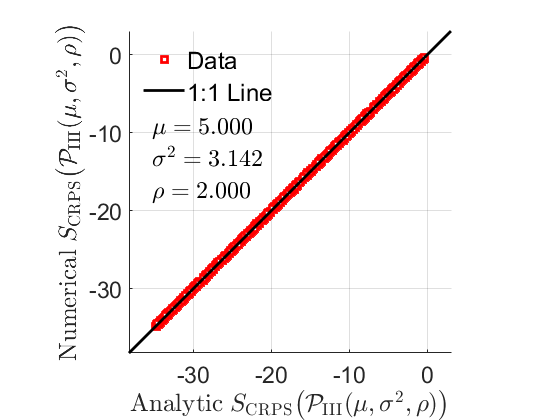

figure(3)
% Plot analytic versus numerical CRPS values
plot(crps_an,crps_num,'rs','markerfacecolor','w','linewidth',2);
xlabel(['${\rm Analytic}\; S_{\rm CRPS}\bigl(\mathcal{P}_{\rm III}' ...
    '(\mu,\sigma^{2},\rho)\bigr)$'],'interpreter','latex','fontsize',18);
ylabel(['${\rm Numerical}\; S_{\rm CRPS}\bigl(\mathcal{P}_{\rm III}' ...
    '(\mu,\sigma^{2},\rho)\bigr)$'],'interpreter','latex','fontsize',18);
axis square
r = range(crps_an(:,1));
xymin = min(crps_an(:,1)) - r/10; xymax = max(crps_an(:,1)) + r/10;
axis([xymin xymax xymin xymax]);
line([xymin xymax],[xymin xymax],'linewidth',2,'color','k');
legend('Data','1:1 Line','fontsize',18,'location','northwest'); 
legend boxoff
text(xymin + 0.07*(xymax - xymin),xymin + 0.7*(xymax-xymin), ...
    char(strcat('$\mu =',{' '},num2str(mu,'%5.3f'),'$')), ...
    'interpreter','latex','fontsize',18);
text(xymin + 0.07*(xymax - xymin),xymin + 0.6*(xymax-xymin), ...
    char(strcat('$\sigma^{2} =',{' '},num2str(s2,'%5.3f'),'$')), ...
    'interpreter','latex','fontsize',18);
text(xymin + 0.07*(xymax - xymin),xymin + 0.5*(xymax-xymin), ...
    char(strcat('$\rho =',{' '},num2str(rho,'%5.3f'),'$')), ...
    'interpreter','latex','fontsize',18);
set(gca,'fontsize',17,'box','off'); set(gcf,'color','w'); grid on

% Print some superificial errors to screen
max_err = max(abs(crps_num-crps_an)) 

max_err = 0.1969

mean_err = mean(abs(crps_num-crps_an))

mean_err = 0.0472

`Notes: perhaps for later`

%   alpha : 4 / sigma^2                --> Eps (WRONG IN CODE: 4/rho^2 - RELATED TO SOMETHING ELSE)
%   beta : 0.5 * sigma * abs(rho)      --> beta
%   xi : mu - 2*sigma/rho              --> xi

% Check int gamma(a+b,x)e^-x x^(a-1)dx
% Check int Gamma(a+b,x)e^-x x^(a-1)dx
% Created a function   gammalow(a,x) = gamma(a,x)
%                      gammaup(a,x) = Gamma(a,x)

% gammainc(x,a+b,'upper') = 1 - gammainc(x,a+b,'lower')
% --> gammainc(x,a+b,'upper') = 1 - 1/gamma(a+b) * gamma(a+b,x)      % x.^a * sum( (-x(i)).^n ./ ( (a+n) .* nper ) )

% --> gammainc(z,a+b,'upper') = 1 - gammainc(z,a+b,'lower')        CORRECT
% --> 1/gamma(a+b) Gamma(a+b,x) = 1 - 1/gamma(a+b) gamma(a+b,x)    CORRECT
% --> 1/gamma(a+b) gamma(a+b,x) - 1 =  - 1/gamma(a+b) Gamma(a+b,x) --> RIGHT INTEGRAL CRPS
% --> Gamma(a+b,x) = gamma(a+b)*(1 - 1/gamma(a+b) * gamma(a+b,x))
% --> Gamma(a+b,x) = gamma(a+b) - gamma(a+b,x)                     CORRECT
% --> int Gamma(a+b,x)e^-x x^(a-1)dx
% --> int (1 - gamma(a+b,x))e^-x x^(a-1)dx
% --> - sum term + \int(gamma(a)e^-x x^(a-1)dx
% --> - sum term - gamma(a)*igamma(a, t)
% --> - sum term - gamma(a)*gamma(a) * gammainc(t,a,'upper')
% Also: gamma(a,x) + Gamma(a,x) = gamma(a)
